# **channerReader의 파일 유형별 read 함수 정리**

# **변경사항**

channelReader object

# **주의**

## (2) 경로 추가 관련

시작 전에, 이 파일이 들어 있는 폴더를 matlab 경로에 추가해 주세요.

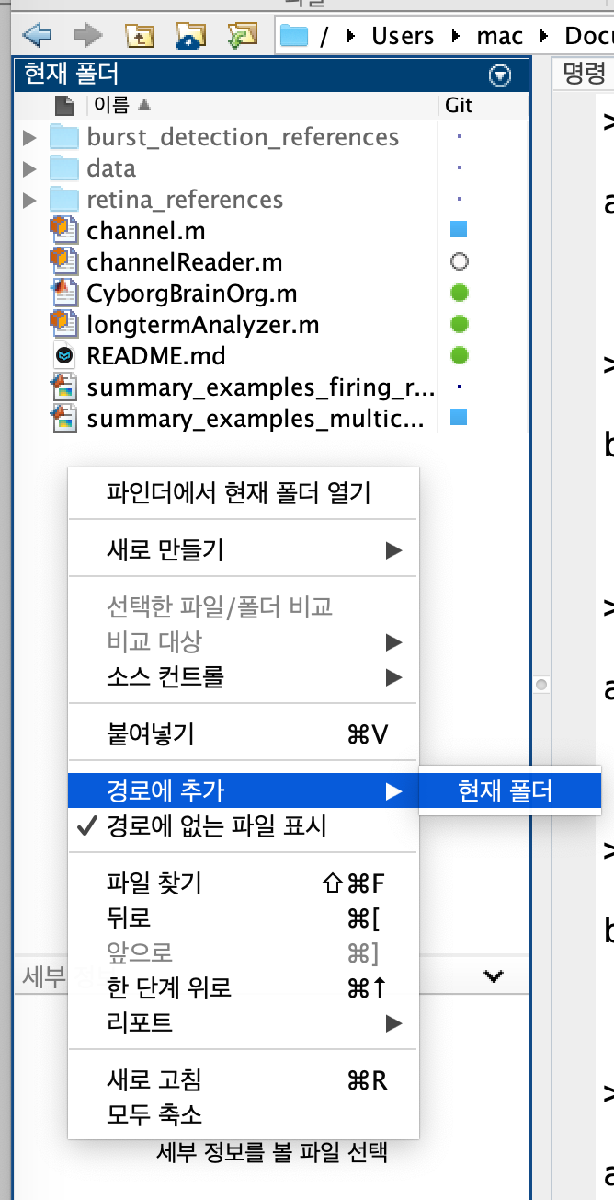

### **0.1.multi-pixel retina data 불러와 channel object 만들기**

**parameter 5개**

- `filename`: 이 파일(mlx)와 같은 디렉토리에 데이터 파일이 있을 경우 그 파일이름만, 다른 디렉토리에 있을 경우 전체 경로 포함 입력. 단, 이 파일(mlx)가 있는 폴더의 하위 디렉토리일 경우 현재 폴더까지의 경로는 ./로 줄여 표현 가능(아래 예제 코드 참고)

- `sampleRate` : 데이터 측정 sampling rate(Hz)

- `organoid`**:** organoid 번호 (관리를 위한 번호, 제한 없음) 

- `channel`: channel 번호 (관리를 위한 번호, 제한 없음) 

- `month`: month. 나중에 month별로 종합할 때 사용됨 (관리를 위한 번호, 제한 없음)

reader = channelReader(); %channelReader object 생성
%                                         filename, sampleRate, organoid, channel, month 
tic 
reader.readMultiChannelFile("./data/전체.xlsx");
toc

경과 시간은 53.895580초입니다.


### **0.2.**

%                                 organoid, pixel numbers, month 
pixels = reader.readManyChannelsFromFile(1, 1:64, 1);

ani = animatedPixelMaker(8,8);
for rowIdx = 1:8
    for colIdx = 1:8
        ani.addPixel(rowIdx,colIdx, pixels{ (rowIdx - 1)*8 + colIdx })
    end
end


 In the (1, 1)th pixel,
Added a channel object with 165 spikes, timerange 9.814671e+00 - 1.283449e+01(s) 
 Current total number of channels = 1

 In the (1, 2)th pixel,
Added a channel object with 226 spikes, timerange 9.814671e+00 - 1.283449e+01(s) 
 Current total number of channels = 1

 In the (1, 3)th pixel,
Added a channel object with 237 spikes, timerange 9.814671e+00 - 1.283449e+01(s) 
 Current total number of channels = 1

 In the (1, 4)th pixel,
Added a channel object with 404 spikes, timerange 9.814671e+00 - 1.283449e+01(s) 
 Current total number of channels = 1

 In the (1, 5)th pixel,
Added a channel object with 452 spikes, timerange 9.814671e+00 - 1.283449e+01(s) 
 Current total number of channels = 1

 In the (1, 6)th pixel,
Added a channel object with 200 spikes, timerange 9.814671e+00 - 1.283449e+01(s) 
 Current total number of channels = 1

 In the (1, 7)th pixel,
Added a channel object with 186 spikes, timerange 9.814671e+00 - 1.283449e+01(s) 
 Current total number o


ani.applyBandPassFilter([300,3000])
ani.detectSpikes(5,2,2)

number of spikes found : 29
number of spikes found : 66
number of spikes found : 80
number of spikes found : 209
number of spikes found : 220
number of spikes found : 40
number of spikes found : 42
number of spikes found : 120
number of spikes found : 99
number of spikes found : 60
number of spikes found : 9
number of spikes found : 213
number of spikes found : 218
number of spikes found : 218
number of spikes found : 215
number of spikes found : 2
number of spikes found : 100
number of spikes found : 47
number of spikes found : 214
number of spikes found : 215
number of spikes found : 217
number of spikes found : 28
number of spikes found : 40
number of spikes found : 22
number of spikes found : 44
number of spikes found : 49
number of spikes found : 65
number of spikes found : 196
number of spikes found : 206
number of spikes found : 105
number of spikes found : 77
number of spikes found : 2
number of spikes found : 76
number of spikes found : 210
number of spikes found : 204
number 

pixel1 등의 변수명 위에 커서를 올려 보면 bandpass filter, detectSpikes가 적용되었음을 알 수 있다.

pixel1 = pixels{1}

pixel1 =   channel - 속성 있음:

              organoidNum: 1
               channelNum: 1
                    month: 1
                       sf: 2.4414e+04
                  msPerTs: 0.0410
              nTimestamps: 73727
                startTime: 9.8147
            endTimeApprox: 12.8345
           durationApprox: 3.0198
                        t: [1×73727 double]
                      raw: [1×73727 double]
                 filtered: [1×73727 double]
        timestampsPrePeak: 49
       timestampsPostPeak: 49
          spikeTimestamps: [1×165 double]
    spikeTimestampsMatrix: []
           spikeWaveforms: [165×99 double]
                  nSpikes: 165
                 PCScores: []
             explainedVar: []
                 clusters: []
                nClusters: []
        nSpikesPerCluster: []
     totalMeanSpikeStruct: [1×1 struct]
         meanSpikesStruct: []
             ISIbeforePCA: []
                      IS

pixel2 =   channel - 속성 있음:

              organoidNum: 1
               channelNum: 2
                    month: 1
                       sf: 2.4414e+04
                  msPerTs: 0.0410
              nTimestamps: 73727
                startTime: 9.8147
            endTimeApprox: 12.8345
           durationApprox: 3.0198
                        t: [1×73727 double]
                      raw: [1×73727 double]
                 filtered: [1×73727 double]
        timestampsPrePeak: 49
       timestampsPostPeak: 49
          spikeTimestamps: [1×226 double]
    spikeTimestampsMatrix: []
           spikeWaveforms: [226×99 double]
                  nSpikes: 226
                 PCScores: []
             explainedVar: []
                 clusters: []
                nClusters: []
        nSpikesPerCluster: []
     totalMeanSpikeStruct: [1×1 struct]
         meanSpikesStruct: []
             ISIbeforePCA: []
                      IS

ani.preProcess(5*1e-6, 50) % cutoffVal(특정 측정치 이상의 spike만 고를 때 측정치 기준값), binWidth(millisecond)

colormap list: https://kr.mathworks.com/help/matlab/ref/colormap.html#d123e146353

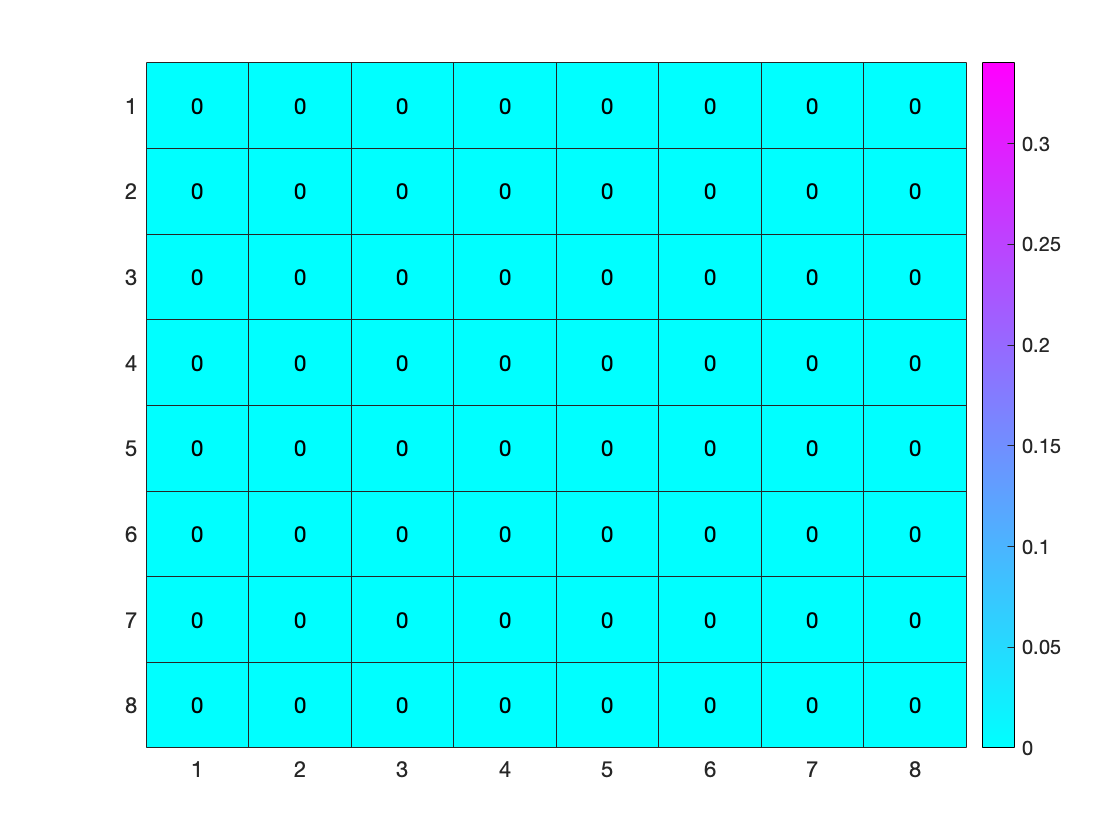

ani.makeAnimatedPixels(cool)

ani.RecordAnimatedPixels(cool, "test.mp4", 5)

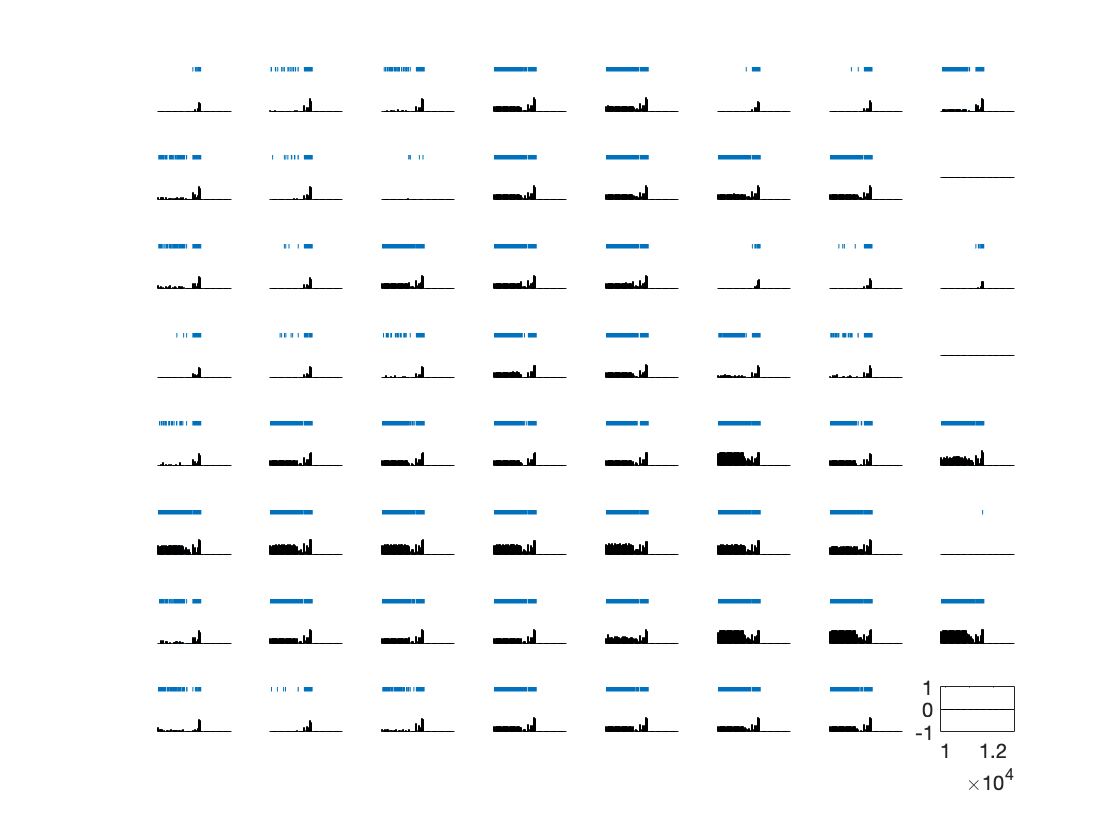

figure;

for rowIdx = 1:8
    for colIdx = 1:8
        pixelNow = ani.pixels{rowIdx, colIdx};
        
        % histogram
        thNow = pixelNow.th;
        edgesNow = pixelNow.edges;
        subplot(8,8,(rowIdx - 1)*8 + colIdx )
        
        % raster 
        selectedSpikesMs = pixelNow.selectedMs{1};
        bar(edgesNow,thNow); %Plot PSTH as a bar graph 
        for i = 1:length(selectedSpikesMs) %data2msPS의 첫 원소부터 마지막 원소까지 (Loop through each spike time )
            line([selectedSpikesMs(i) selectedSpikesMs(i)], [0.9, 1])  % 두 점 (data1msPS(i), 0)과 (data1msPS(i), 1)을 잇는 선, 즉 길이 1짜리 수직선을 그린다(Create a tick mark at x = t1(i) with a height of 1).
        end
        
    end
end

t = get(get(gcf, 'Children'), 'XAxis');
t = t(2:end);
set([t{:}], 'Visible', 'off')
t = get(get(gcf, 'Children'), 'YAxis');
t = t(2:end);
set([t{:}], 'Visible', 'off')
set(get(gcf, 'Children'), 'Color', 'none')

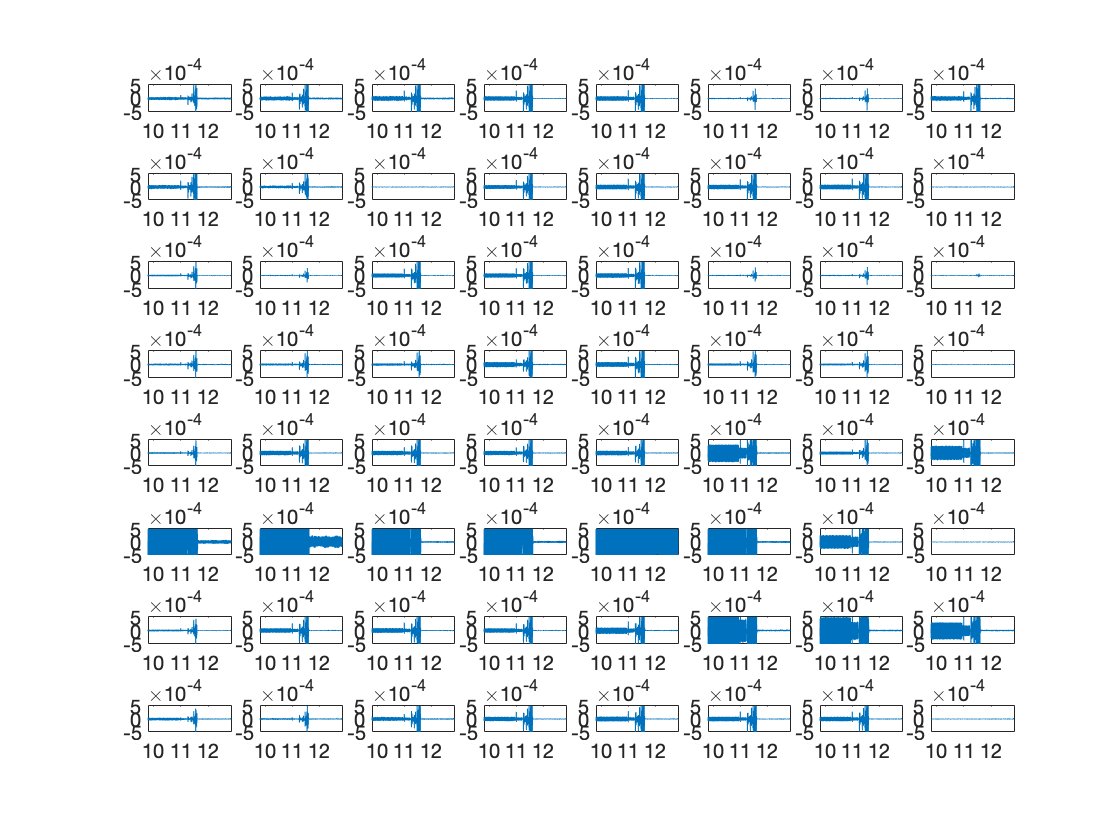

figure;

for rowIdx = 1:8
    for colIdx = 1:8
        channelNow = ani.pixels{rowIdx, colIdx}.channels{1};
        
        subplot(8,8,(rowIdx - 1)*8 + colIdx )
        plot(channelNow.t, channelNow.filtered); %matlab 기본 plot 함수 사용

        ylim([-6,6]*1e-4);%ylim 조절 가능

        end
end